# Using Data In Music

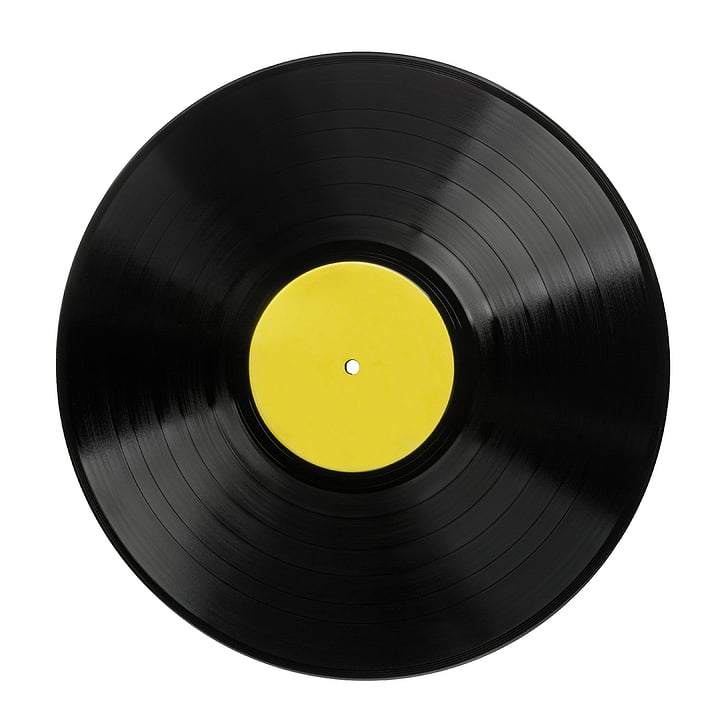

You've been hired by a record label in order to organize their artist's data (*a company that publishes artist's music and promotes it)*.

Before getting started, think about how you would store the following items, and what data types they would be.

- What data type would an artist's name be?

- How would you store albums, as a list/array of songs?

- How would you store the amount of listens or streams a song gets?

## Problem 1: Top 10 Tracks

The record label wants you to organize the top 10 most popular tracks in the US today. Create a variable that stores the names of each of the following songs:

- A Bar Song

- Please Please Please

- Nasty

- Not Like Us

- I Had Some Help

- BIRDS OF A FEATHER

- MILLION DOLLAR BABY

- Good Luck, Babe!

- Houdini

- Espresso

%this cleans the workspace and command window
clc; clear;

%YOUR CODE GOES HERE%
%song_list = []
%make sure this list is in the same order as above, we will use it again in Part
%3, make sure you keep the variable name "song_list" for Part 3 to work!


 

## Problem 2: Average Top 10 Streams

The record label is interest in knowing the average amounts of streams/listens that songs in the top 10 are reaching. To do this you will need to store the number of listens from each song in a variable and find the mean average. Here are the number of listens below:

- A Bar Song: 328,558,379

- Please Please Please: 98,201,064

- Nasty: 36,651,626

- Not Like Us: 338,868,818

- I Had Some Help: 266,320,519

- BIRDS OF A FEATHER: 242,086,893

- MILLION DOLLAR BABY: 416,636,466

- Good Luck, Babe!: 187,070,573

- Houdini: 126,246,936

- Espresso: 580,570,678

%YOUR CODE GOES HERE%
%stream_counts = []
%make sure this list is in the same order as above, we will use it again in Part
%3

%what function is used to find the mean?:
%avg_counts = ...

%we can use this statement to display the value after saving it as a
%variable:
%disp(avg_counts)

%if you use "format longG you can display the answer in standard notation
%instead of scientific notation (this will change it for the entire
%document)

format longG



 

## Problem 3: What Song is the Most Popular?

The record label wants you to see which of these songs is the most popular, which means we need to learn some new techniques!

 Follow along with the coding cells below and make use of what you created in Problem 1 and 2.

%before we are able to print out which song has the most streams, we need
%to combine the two lists that we made (make sure they are in the correct
%order)

%we can create a 2D array the same way we did in the last livescript by
%using a ";" and adding our other arrays to a new array

full_list = [song_list ; stream_counts]
 

You can make sure that this line of code did what it was supposed to by opening the variable it made in the workspace. Double click on the name "full_list" in the workspace and it will open a spreadsheet of the values in their respective rows:

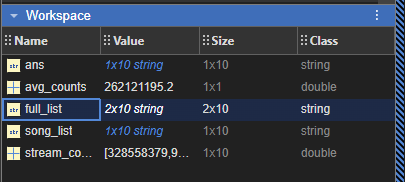

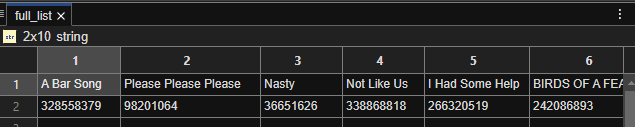

%now that we have one row with the song titles and one row with the
%steam counts, we can print them seperately as well

%this will print all of the song titles
full_list(1,:)

%this will print all of the stream counts
full_list(2,:)

%so how would we find the max stream count? let's try using the max()
%function on the 2nd row of the array
 

%the only issue we have is that when we added the arrays together, it made
%the stream_counts a string! so how do we find the maximum of a string?
%well first we need to do something called "casting" and make the list of
%strings into a list of doubles (numerical values)

%we can cast the variable as a double by using "double()" and then use the
%max function as seen below:

max(double(full_list(2,:)))

 

%this gives the same answer as stream_counts, so you might wonder why we do it like this:

max(stream_counts)

 

%but, since we have the first row of the list as the song names we can use
%a print statement and the full_list variable to do this:

%we can save the max number of listens as a variable
top_song_streams = max(double(full_list(2,:)))

%then we can use the "find" function to find the index of the max number of
%listens

max_index = find(double(full_list(2,:)) == top_song_streams)
 

%for the above statement^^^:
%we could also use --> max_index = find(stream_counts == top_song_streams)
%since the arrays are in the same order

%the above code block should return a "10" since the song with most number of
%listens is the 10th song in the list "Espresso", we can save the name of
%this song from the full list by using the line of code below:

top_song_name = full_list(1, max_index)
 

%now let's display it as a complete statement by using the fprintf() function
%we can add the variables we want to print at the end of our function and
%then use "%s" when we want to format the variable as a string in the
%statement and "%d" when we want to format the variable as an integer
%(number without decimal places, which are called floating points)

fprintf("The most streamed song in the top 10 list is %s with %d total streams!", top_song_name, top_song_streams)

%if we used "%f" instead of "%d" we would get floating points, in other
%words, a bunch of zeroes after the decimal places
 

### Problem 3 Continued: Extra Practice

Now that you know about indexing a 2D array (a list with rows and columns), and how to format a print statement, why don’t you try finding the stream count and name of the least listened to song in the list!

%first we need to find the minimum number of streams
%YOUR CODE%


%then we need to find the index of the minimum value to find the name of
%the song in the first row of the array
%YOUR CODE%


%the we can save the name of the song by using the index of the minimum
%number of streams (since they are in the same order)
%YOUR CODE%


%then we can use the print statement like in the previous problem:
%YOUR CODE%
 